# Base de un subespacio - Espacio columna de una matriz

### Ejemplo 1

Determine una base del subespacio H.

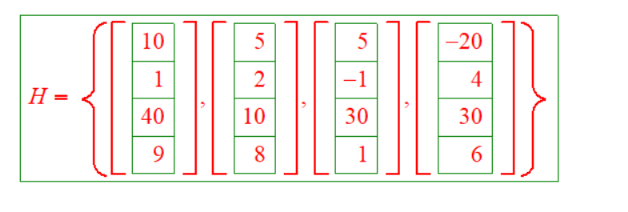

% Crear la matriz con los vectores en columna
v1 = [10 1 40 9]'

v1 =     10
     1
    40
     9


v2 = [5 2 10 8]'

v2 =      5
     2
    10
     8


v3 = [5 -1 30 1]'

v3 =      5
    -1
    30
     1


v4 = [-20 4 30 6]'

v4 =    -20
     4
    30
     6


A = [v1 v2 v3 v4]

A =     10     5     5   -20
     1     2    -1     4
    40    10    30    30
     9     8     1     6


Llevando la matriz A a su forma escalonada reducida e identicando la posición de los pivotes en las columnas.

[EA, p] = rref(A)

EA =      1     0     1     0
     0     1    -1     0
     0     0     0     1
     0     0     0     0


p =      1     2     4


% Obteniendo la base del subespacio H
B = (A (:, p)) %#ok<*NASGU>

B =     10     5   -20
     1     2     4
    40    10    30
     9     8     6


### Comando para obtener una base del subespacio H

Una vez que hemos formado la matriz A, ejecutamos el comando colspace, para ello la matriz debe ser definida simbolicamente

% Ingresando l a Matriz A, usando  el comando "sym"
A = sym([10 5 5 -20 ; 1 2 -1 4 ; 40 10 30 30 ; 9 8 1 6]) 

$$A = \left(\begin{array}{cccc} 10 & 5 & 5 & -20\\ 1 & 2 & -1 & 4\\ 40 & 10 & 30 & 30\\ 9 & 8 & 1 & 6 \end{array}\right)$$

B = colspace (A)

$$B = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ \frac{16}{45} & \frac{25}{9} & \frac{1}{15} \end{array}\right)$$

### Problema 1

#### Considere el subespacio  

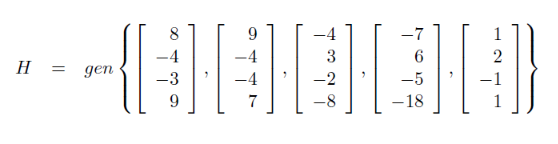

Determine una base del subespacio H

% Defina la matriz R con los vectores que generan H
R = [8 9 -4 -7 1 ; -4 -4 3 6 2 ; -3 -4 -2 -5 -1 ; 9 7 -8 -18 1]

R =      8     9    -4    -7     1
    -4    -4     3     6     2
    -3    -4    -2    -5    -1
     9     7    -8   -18     1


### Problema 2

Considere el subespacio  

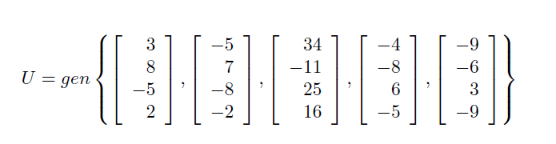

Determine una base del subesapcio U

R = [3 -5 34 -4 -9 ; 8 7 -11 -8 -6 ; -5 -8 25 6 3 ; 2 -2 16 -5 -9]

R =      3    -5    34    -4    -9
     8     7   -11    -8    -6
    -5    -8    25     6     3
     2    -2    16    -5    -9


rref(R)

ans =     1.0000         0    3.0000         0    0.3333
         0    1.0000   -5.0000         0    0.6667
         0         0         0    1.0000    1.6667
         0         0         0         0         0


# ESPACIO FILA DE UNA MATRIZ

Para encontrar  una base del espacio de las filas de una matriz A, lo que haremos es convertir cada fila en una columna, es decir hallamos la matriz transpuesta de la matriz A, seguidamente encontramos la base del espacio columna de la matriz transpuesta de A.

### Ejemplo:

Determine una base del espacio de las fila (espacio fila) de la matriz 

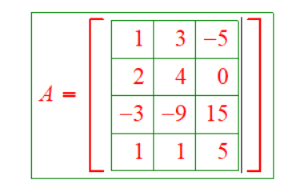

Definimos la matriz 

A = [1 3 -5 ; 2 4 0 ; -3 -9 15 ; 1 1 5]

A =      1     3    -5
     2     4     0
    -3    -9    15
     1     1     5


% Definimos la matriiz transpuesta de A y lo guardamos en B
B = A'

B =      1     2    -3     1
     3     4    -9     1
    -5     0    15     5


[EB, p] = rref(B)

EB =      1     0    -3    -1
     0     1     0     1
     0     0     0     0


p =      1     2


B = A(:, p)

B =      1     3
     2     4
    -3    -9
     1     1


# ESPACIO NULO DE UNA MATRIZ A

Considere la matriz A 

De acuerdo a la definición el espacio nulo de A es dado por 

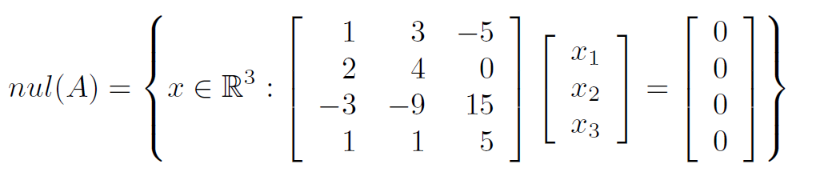

Este conjunto es un subepacio de R3 y se desea obtener una base.

Definimos la matriz A  

A = [1 3 -5 ; 2 4 0 ; -3 -9 15 ; 1 1 5]

A =      1     3    -5
     2     4     0
    -3    -9    15
     1     1     5


Usando el comando de matlab null

B = null(A, 'r')

B =    -10
     5
     1


Como hay una sola columna, entonces la base tiene un solo vector y su dimensión es 1

Usando operaciones elementales

A = [1 3 -5 ; 2 4 0 ; -3 -9 15 ; 1 1 5]

A =      1     3    -5
     2     4     0
    -3    -9    15
     1     1     5


b = [0 0 0 0]'

b =      0
     0
     0
     0


Aa = [A b]

Aa =      1     3    -5     0
     2     4     0     0
    -3    -9    15     0
     1     1     5     0


lo llevamos a su forma escalonada 

[EAA] = rref(Aa)

Relacion entre el espacio fila y columna

% Ejemplo 
A = sym([1 3 -2 0 2 0 ; 2 6 -5 -2 4 -3 ; 0 0 5 10 0 15 ; 2 6 0 8 4 18])

$$A = \left(\begin{array}{cccccc} 1 & 3 & -2 & 0 & 2 & 0\\ 2 & 6 & -5 & -2 & 4 & -3\\ 0 & 0 & 5 & 10 & 0 & 15\\ 2 & 6 & 0 & 8 & 4 & 18 \end{array}\right)$$

rref(A)

$$ans = \left(\begin{array}{cccccc} 1 & 3 & 0 & 4 & 2 & 0\\ 0 & 0 & 1 & 2 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B = colspace (A)

$$B = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 10 & -5 & 0\\ 0 & 0 & 1 \end{array}\right)$$

B = colspace (A')

$$B = \left(\begin{array}{ccc} 1 & 0 & 0\\ 3 & 0 & 0\\ 0 & 1 & 0\\ 4 & 2 & 0\\ 2 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

null(A)

$$ans = \left(\begin{array}{ccc} -3 & -4 & -2\\ 1 & 0 & 0\\ 0 & -2 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$